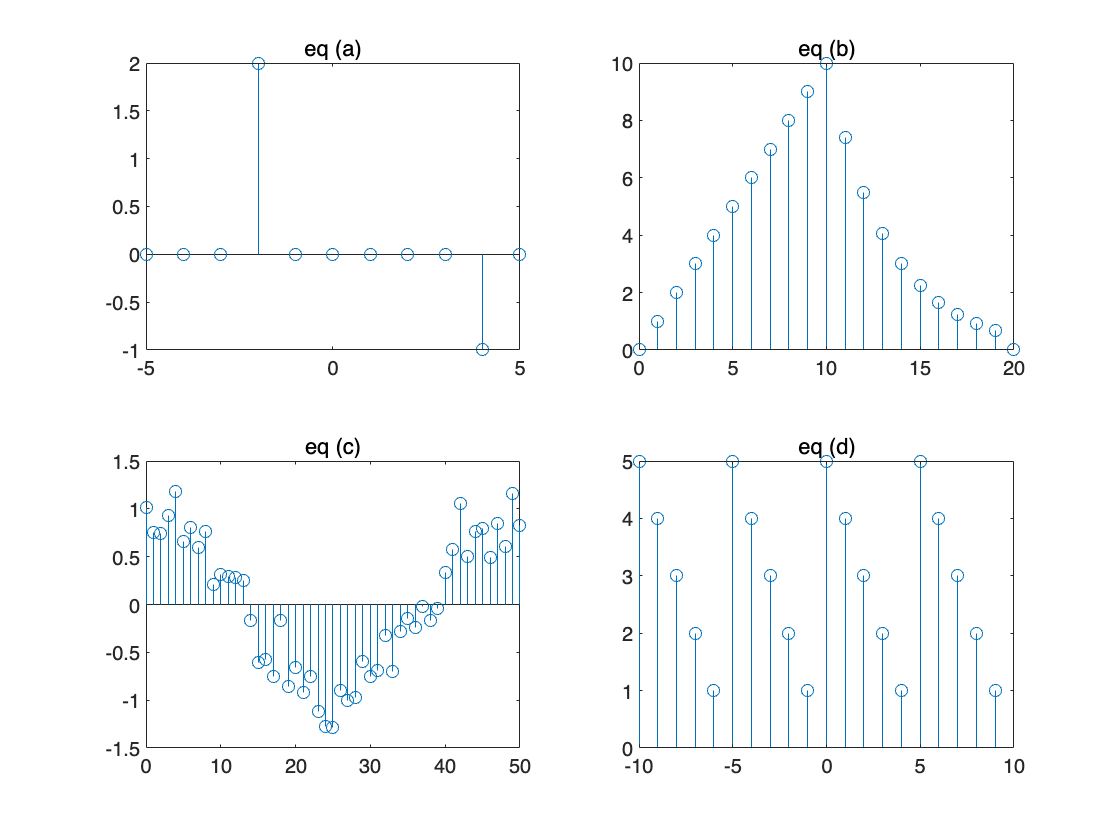

%Ex1)
clc;
close all;
clear all;
clf;
n1 = -5:5;
x1 = 2*impseq(-2,n1(1),n1(end))-impseq(4,n1(1),n1(end));
n2 = 0:20;
x2 = n2.*(stepseq(0, n2(1), n2(end))-stepseq(10, n2(1), n2(end)))+10.*exp(-0.3.*(n2-10)).*(stepseq(10, n2(1), n2(end))-stepseq(20, n2(1), n2(end)));
n3 = 0:50;
x3 = cos(0.04*pi*n3) + 0.2*randn(1, 51);
n4 = -10:9;
s1 = 5:-1:1;
[y_1, n_1] = sigshift(s1,[0:4],-10);
[y_2, n_2] = sigshift(s1,[0:4],-5);
[y_3, n_3] = sigadd(y_1,n_1,y_2,n_2);
[y_4, n_4] = sigshift(y_3,n_3,10);
[x4, n4] = sigadd(y_3,n_3,y_4,n_4);
figure(1)
subplot(2,2,1); stem(n1,x1); title("eq (a)");
subplot(2,2,2); stem(n2,x2); title("eq (b)");
subplot(2,2,3); stem(n3,x3); title("eq (c)");
subplot(2,2,4); stem(n4,x4); title("eq (d)");